# State Estimation of Formation Control Systems

This the final project for course *ET4386 Estimation and Detection*.

clear all;
clc;
close all;

## 1. Data Load

- dt: The time interval

- K: Max iterations

- N: Number of Agents (7)

- M: Number of Edges (12)

- z: Actual positions of each agent (2D position)

- z*: Target positions of each agent

- L: Edge weights ($l_{ij} $: the weight of the edge between positions of the i-th and j-th agent)

- R: The covariance matrix of the noise

load("data.mat");

## 2. Initialization

disp(L); % take a look to the weight

    0.2741   -0.2741   -0.2741    0.1370    0.1370         0         0
   -0.2741    0.6852         0   -0.5482         0         0    0.1370
   -0.2741         0    0.6852         0   -0.5482    0.1370         0
    0.1370   -0.5482         0    0.7537   -0.0685   -0.2741         0
    0.1370         0   -0.5482   -0.0685    0.7537         0   -0.2741
         0         0    0.1370   -0.2741         0    0.2741   -0.1370
         0    0.1370         0         0   -0.2741   -0.1370    0.2741



z_matrix = zeros(7, 2, K); % the matrix containing the positions of all agents for K iterations
z_matrix(:, :, 1) = z;     % initialize the position of the 1-st iteration
k = 1; % current iteration
% u_matrix = zeros(7, 2, K) % control variable matrix

## 3. Control without Noise

The project aims to implement a relative formation control system affected by measurement noise. We will discuss the impact of different estimators and various T noisy measurements on the system.

First, we implement a noise-free relative formation control based on the pseudocode provided in the assignment.

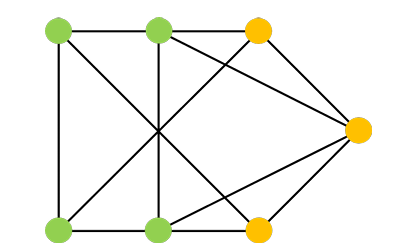

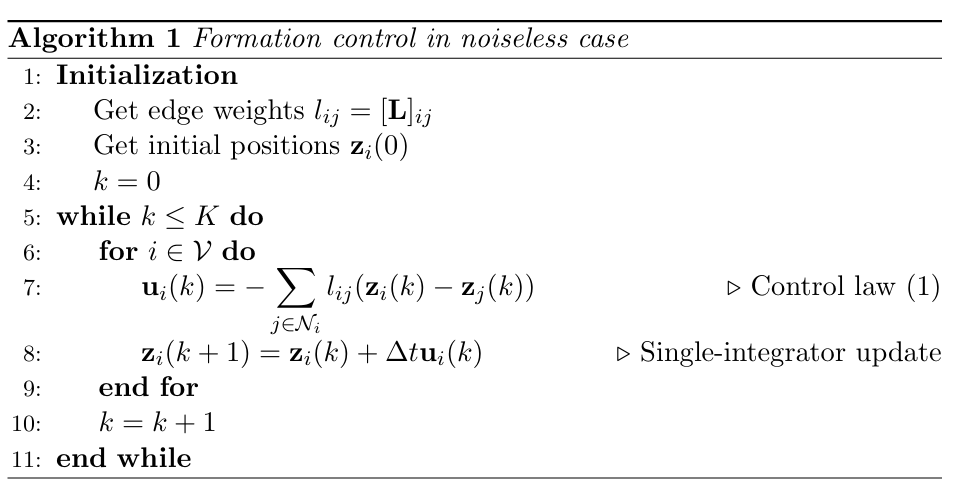

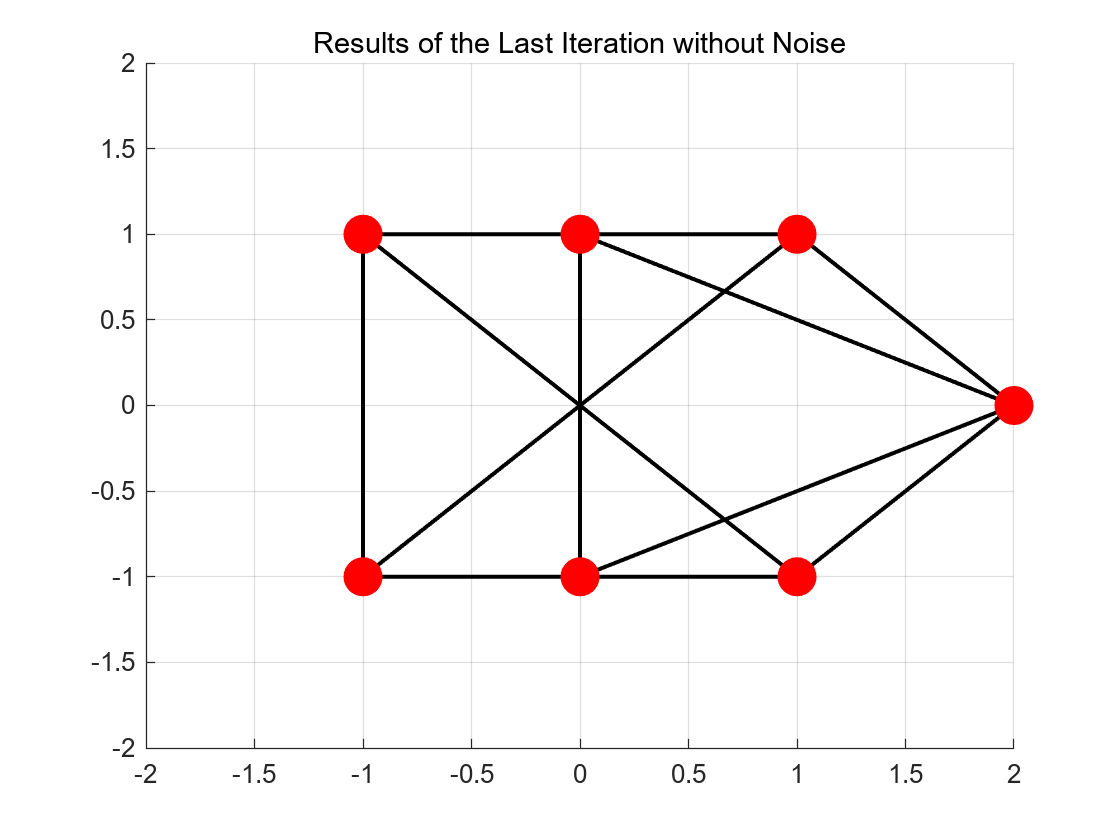

% the hyperparameters used by the reference
% dt = 0.001;
% K = 30000;

dt = 0.1;
K = 4000;

while k <= K
    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix(i, :, k); % get the old position

        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            u_i_k = u_i_k + L(i, j) * (z_matrix(i, :, k) - z_matrix(j, :, k));
        end

        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error = compute_error(z_matrix, z_star, K);

% plot the result
plot_formation(z_matrix(:, :, K));
grid on;
title("Results of the Last Iteration without Noise")
saveas(gcf, fullfile('imgs', 'formation_noiseless.png'));

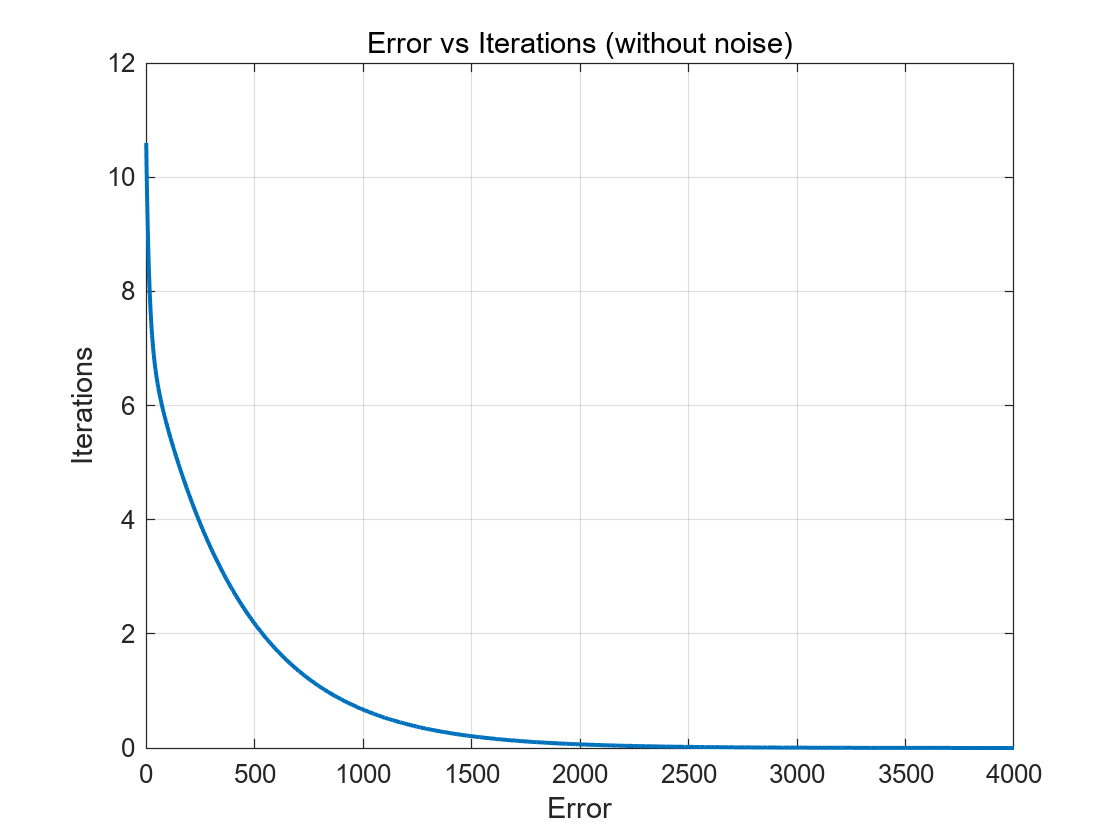

% plot the errors comparing to iterations
figure;
plot(error, 'Linewidth', 1.5); 
xlabel("Error");
ylabel("Iterations");
title("Error vs Iterations (without noise)");
grid on;
saveas(gcf, fullfile('imgs', 'error_noiseless.png'));

## 4. Add Noise and Observation

Next, we simulate the scenario with noise. The noise is added according to covariance matrix R.

The result shows that the noise introduces instability. Overall, there is a convergence trend, but it ultimately fails to converge to the ideal position.

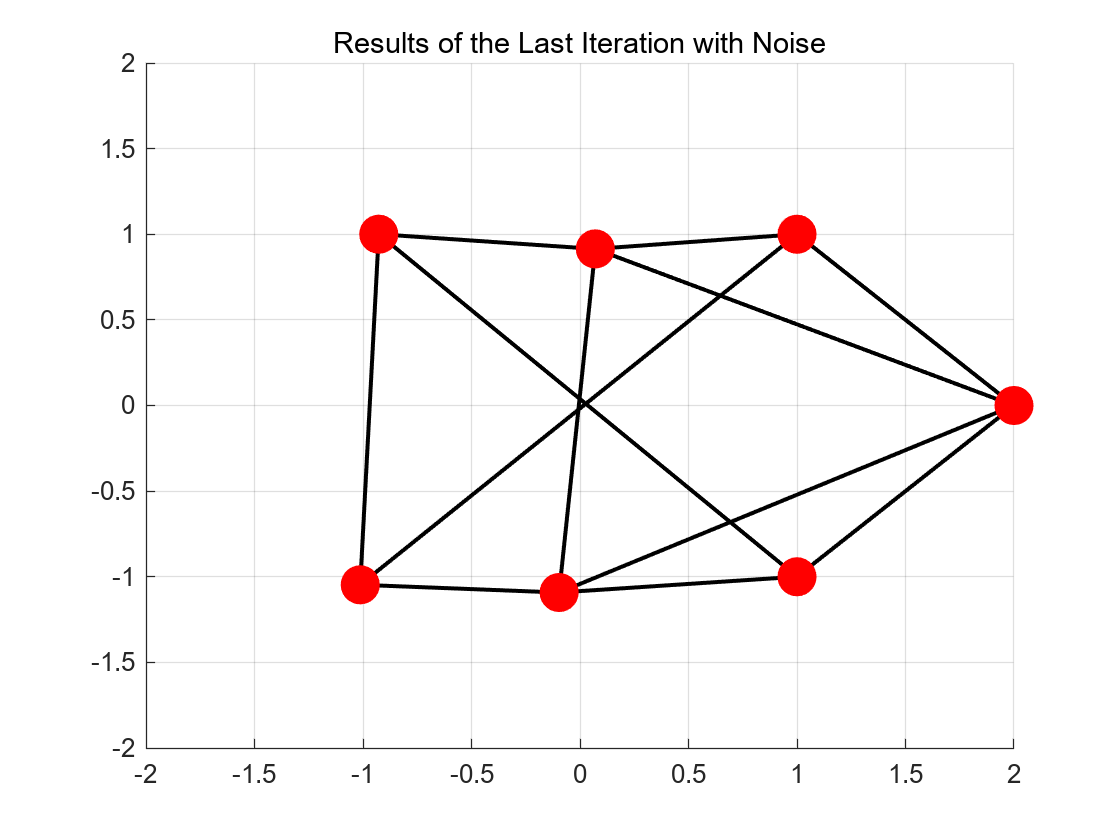

% initialize
z_matrix2 = zeros(7, 2, K);
z_matrix2(:, :, 1) = z;
k = 1;

% retain the observations, i.e. the measurements
% since there are only 12 non-zero edges, only 12 vectors are needed
observations_m = zeros(12, 2, K);

% start iteration
while k <= K
    state_num = 0;

    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix2(i, :, k);
        
        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            y_k = z_matrix2(i, :, k) - z_matrix2(j, :, k) + mvnrnd([0, 0], R);
            u_i_k = u_i_k + L(i, j) * y_k;

            % x_matrix(i, j, :, k) = x; % problematic, only need to retain where L is non-zero.
            % retain the measurement
            % 1. Only retain measurements where L is non-zero 
            %    and not self-loops
            % 2. Only keep non-zero values in the lower triangular 
            %    matrix of L (since L is a symmetric matrix).
            if (L(i, j) ~= 0 && i < j)
                state_num = state_num + 1;
                observations_m(state_num, :, k) = y_k;
            end
        end
        
        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix2(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error_no_noise = error;
error = compute_error(z_matrix2, z_star, K);

% plot the trajectories
plot_formation(z_matrix2(:, :, K));
grid on;
title("Results of the Last Iteration with Noise");
saveas(gcf, fullfile('imgs', 'formation_noise.png'));

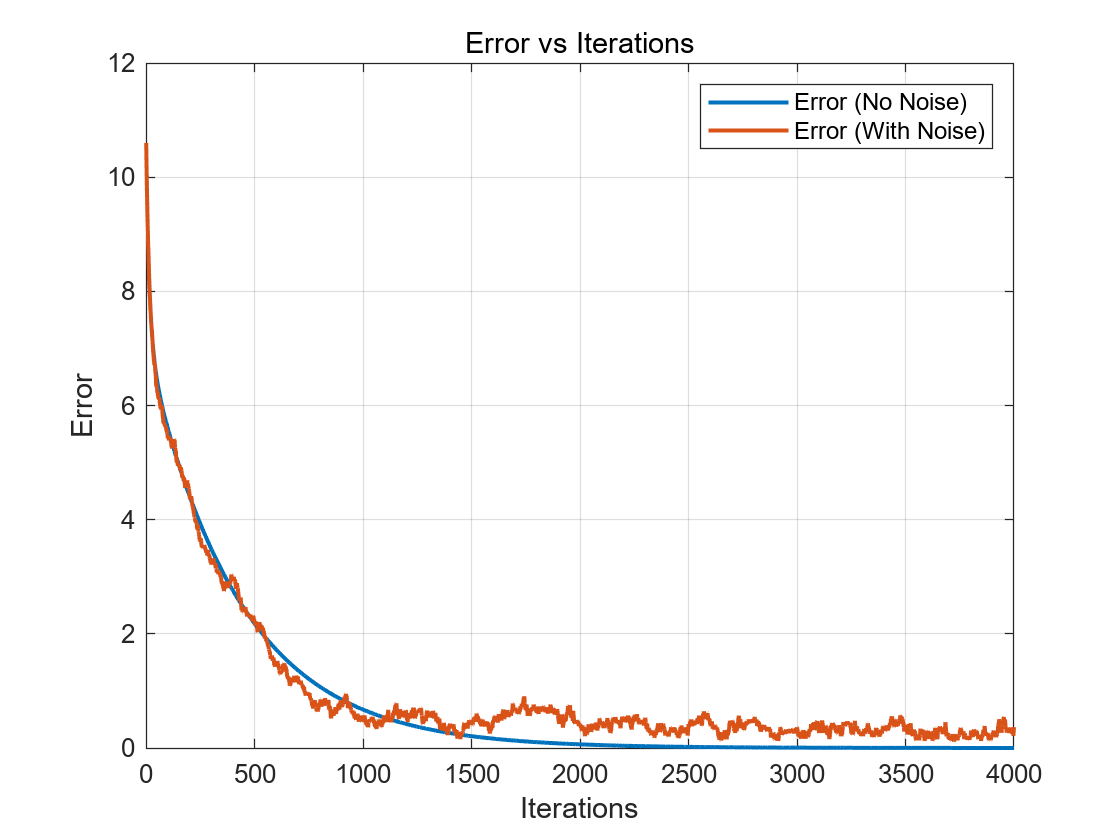

% plot errors compating to iterations
figure;
plot(error_no_noise, "LineWidth", 1.5);
hold on;
plot(error, "LineWidth", 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
legend('Error (No Noise)', 'Error (With Noise)');
title("Error vs Iterations");
saveas(gcf, fullfile('imgs', 'error_noise_vs_noiseless.png'));

## 5. Applying Different Estimators

In the following section, we will apply different estimators with different number of measurements T, and observe their effects.

% Set common parameters for estimators for comparison
max_iter = 4000;    % Maximum number of iterations
T = 10;             % Number of observations per node pair 
dt = 0.1;           % Step size

## 5.1 MLE (Unbiased Estimator)

As described in the given reference, MLE equals to MVUE for a linear Gaussian noise case. 

%% MLE (T=10)
% Initialize parameters

z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix
z_matrix_2(:, :, 1) = z;                % Initial state
vec_T = ones(T, 1);                     % T x 1 vector of ones
dimension = 2;                          % Dimension of the state
I_Dimension = eye(dimension);           % D x D identity matrix

% Start iteration
for k = 1:max_iter
    for i = 1:N
        % Initialize input
        u_i_k = zeros(1, dimension);
        
        % Iterate over neighboring nodes
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % Construct measurements
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz_true' + vij_m'; % Noisy observations
                
                % Compute MLE solution
                Sigma_v = kron(R, eye(T)); % Covariance matrix
                Sigma_v_inv = inv(Sigma_v); % Inverse of covariance matrix
                dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE solution
                
                % Accumulate input
                u_i_k = u_i_k + L(i, j) * dz_mle';
            end
        end
        
        % Update state (fixed nodes are not updated)
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end



## Plots（MLE）

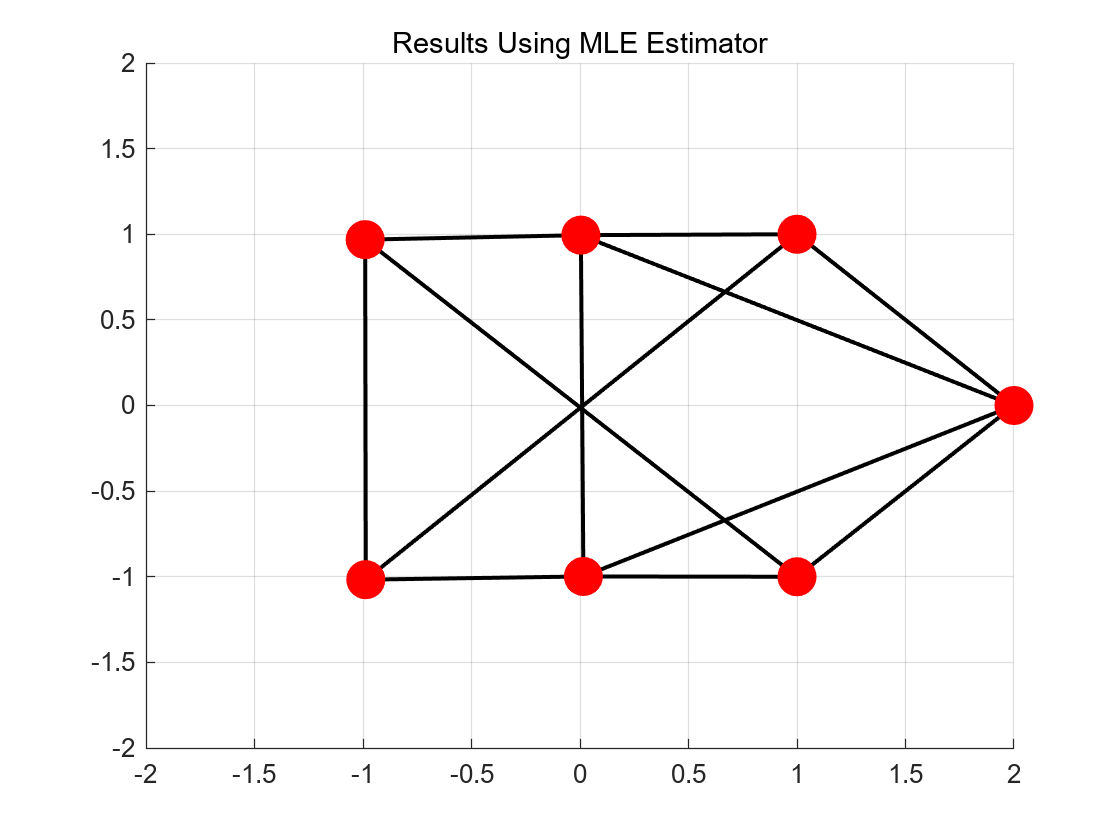

% only plot the final formation
figure;
plot_formation(z_matrix_2(:, :, max_iter)); 
grid on;
title("Results Using MLE Estimator");
saveas(gcf, fullfile('imgs', 'formation_mle.png'));

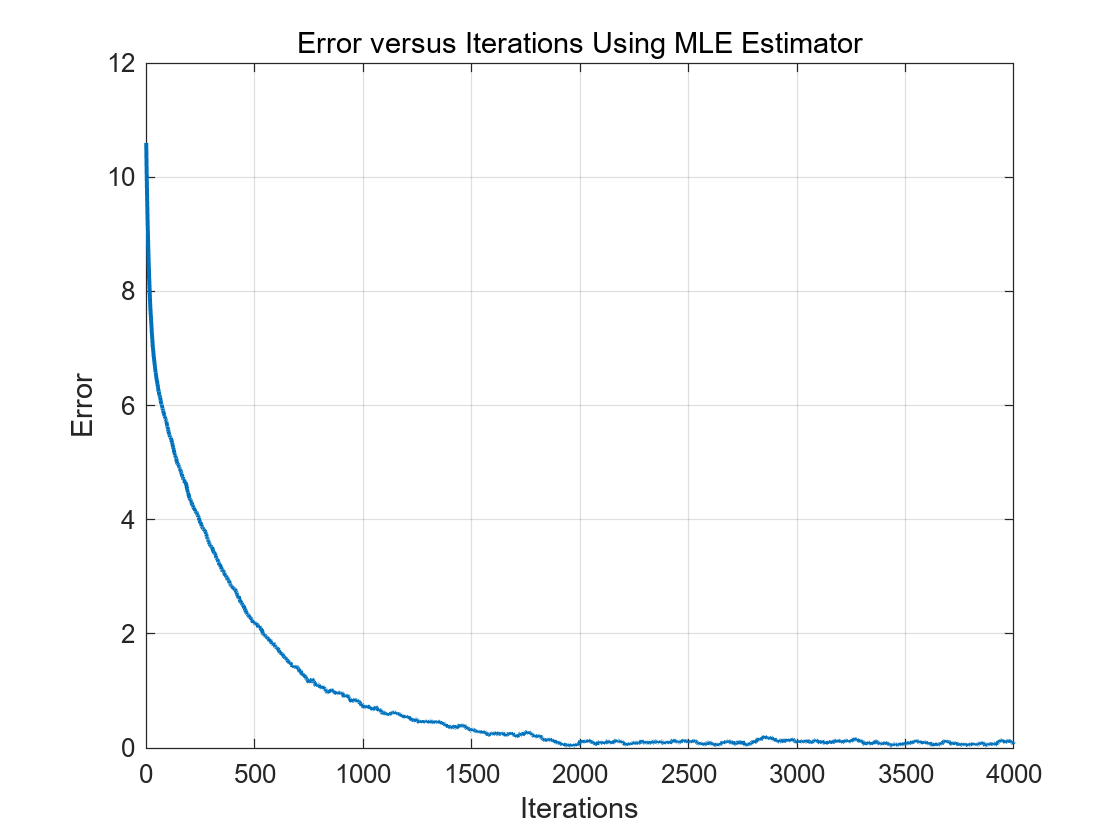

figure;
error_MLE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using MLE Estimator");
plot(error_MLE, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using MLE Estimator");
saveas(gcf, fullfile('imgs', 'error_mle.png'));

## 5.2 LSE Estimator

% 5.2 LSE (Least Squares Estimation)

% Initialize parameters
z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix
z_matrix_2(:, :, 1) = z;                % Initial state
vec_T = ones(T, 1);                     % T x 1 vector of ones
dimension = 2;                          % Dimension of the state
I_Dimension = eye(dimension);           % D x D identity matrix

% Begin iteration
for k = 1:max_iter
    for i = 1:N
        % Initialize input for node i
        u_i_k = zeros(1, dimension);
        
        % Process neighboring nodes
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % Construct measurements with noise
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T))); % Noise vector
                H = kron(vec_T, I_Dimension); % Observation matrix
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % True state difference
                x_state_m = H * dz_true' + vij_m'; % Noisy observations
                
                % Compute LSE solution
                dz_lse = inv(H' * H) * (H' * x_state_m); % LSE solution

                % Accumulate input from neighbors
                u_i_k = u_i_k + L(i, j) * dz_lse';
            end
        end
        
        % Update state for non-fixed nodes
        if i == 1 || i == 2 || i == 3 % Fixed nodes remain unchanged
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k; % Update state
        z_matrix_2(i, :, k + 1) = z_i_k_new; % Store updated state
    end
end



## Plots（LSE）

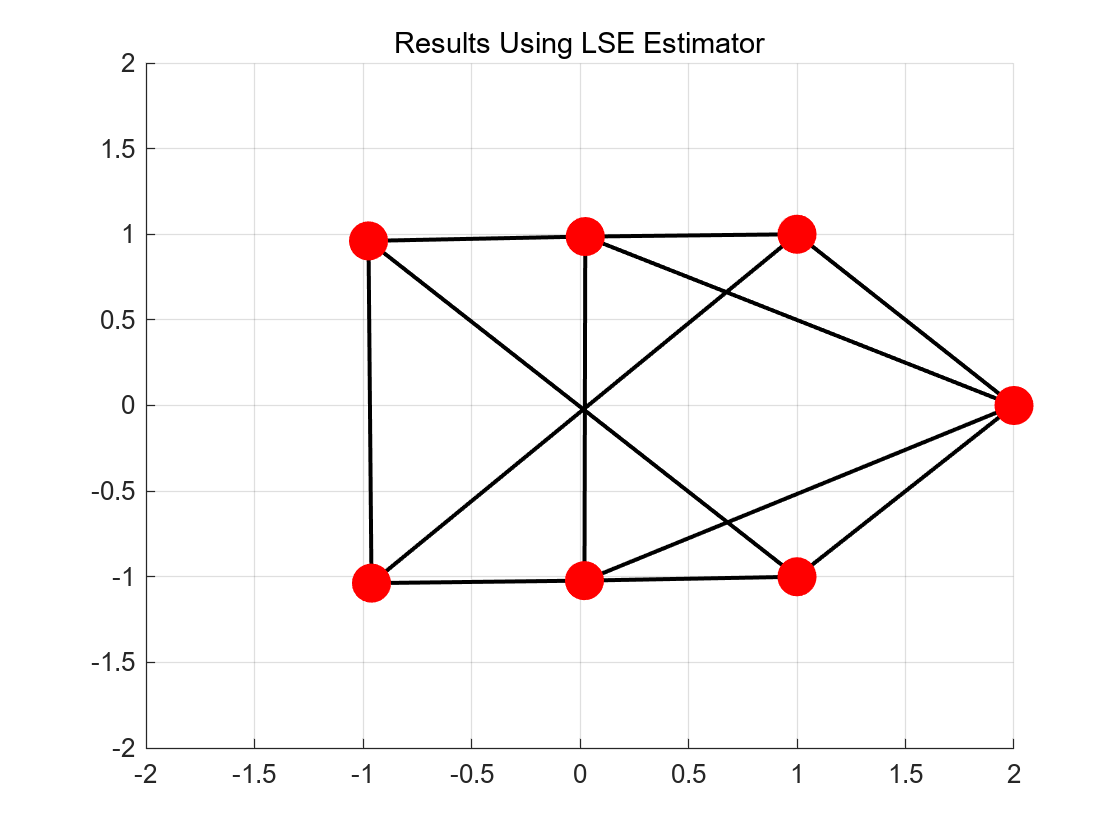

% Visualize results
figure;
plot_formation(z_matrix_2(:, :, max_iter)); % Plot the final formation
grid on;
title("Results Using LSE Estimator"); % Title for the plot
saveas(gcf, fullfile('imgs', 'formation_lse.png')); % Save plot as image

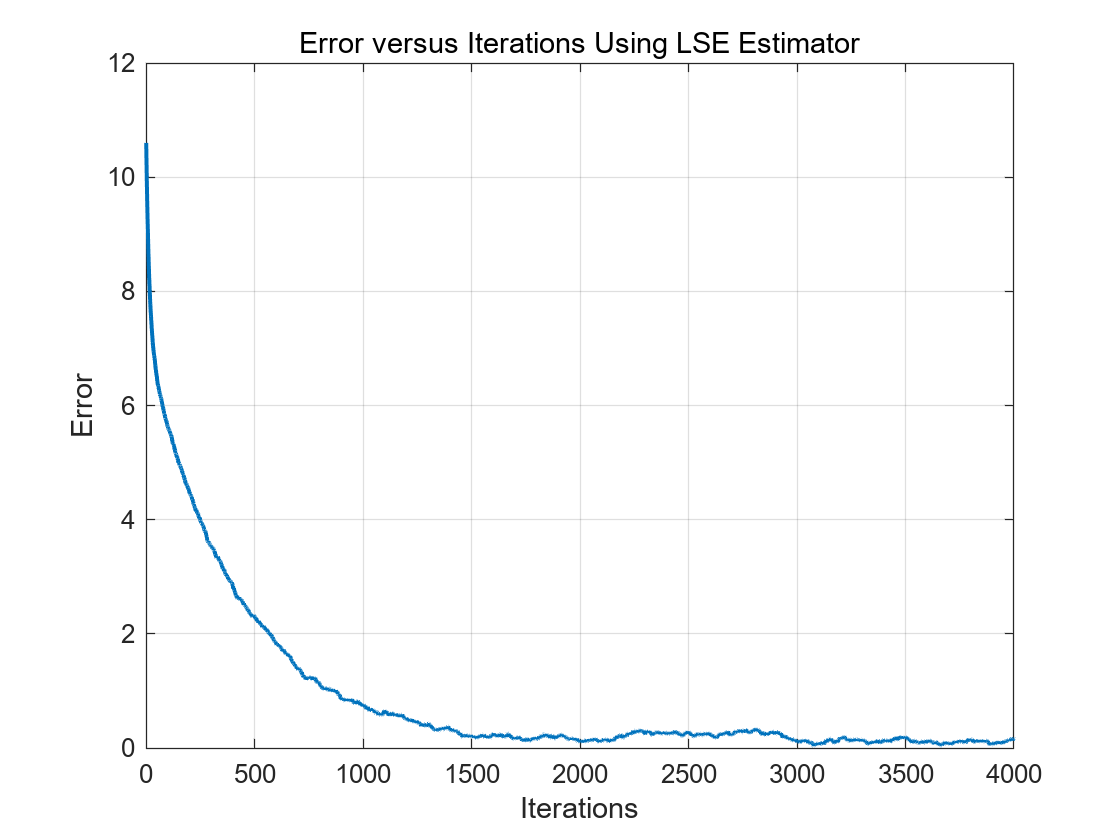


figure;
error_LSE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using LSE Estimator");
plot(error_LSE, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using LSE Estimator");
saveas(gcf, fullfile('imgs', 'error_lse.png'));

## 5.3 Wiener Filter

%% 5.3 Wiener Estimator

% Initialize parameters
z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix (7 nodes, 2 dimensions, k iterations)
z_matrix_2(:, :, 1) = z;                % Initial state
dimension = 2;                          % State dimension
vec_T = ones(T, 1);                     % T x 1 vector of ones
I_Dimension = eye(dimension);           % 2 x 2 identity matrix
R_extended = kron(eye(T), R);           % Noise covariance matrix

% Iterative process
for k = 1:max_iter
    for i = 1:N
        % Step 1: Initialize input for node i
        u_i_k = zeros(1, dimension);
        
        % Step 2: Process neighboring nodes
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % Generate noisy observations
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % True relative state (1x2)
                vij_m = mvnrnd(zeros(1, T * dimension), R_extended); % Noise vector
                H = kron(vec_T, I_Dimension);                       % Measurement matrix (T*2 x 2)
                x_state_m = H * dz_true' + vij_m';                  % Noisy observations (T*2 x 1)
                
                % Step 3: Dynamically compute Wiener filter covariance matrices
                R_ss = dz_true' * dz_true;                          % Autocorrelation of the true signal (2x2)
                R_xx = H * R_ss * H' + R_extended;                  % Covariance of the observed signal (T*2 x T*2)
                C_theta_x = R_ss * H';                              % Cross-covariance between signal and observation (2xT*2)
                
                % Step 4: Compute Wiener filter weight matrix
                W = C_theta_x / R_xx;                               % Wiener filter weights (2xT*2)
                
                % Step 5: Estimate relative state using Wiener filter
                dz_estimate = W * x_state_m;                        % Estimated relative state (2x1)
                
                % Step 6: Accumulate input
                u_i_k = u_i_k + L(i, j) * dz_estimate';
            end
        end
        
        % Step 7: Update state for non-fixed nodes
        if i == 1 || i == 2 || i == 3 % Fixed nodes remain unchanged
            u_i_k = 0; % Input for fixed nodes is zero
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k; % Update state
        z_matrix_2(i, :, k + 1) = z_i_k_new;          % Save updated state
    end
end



## Plots（Wiener）

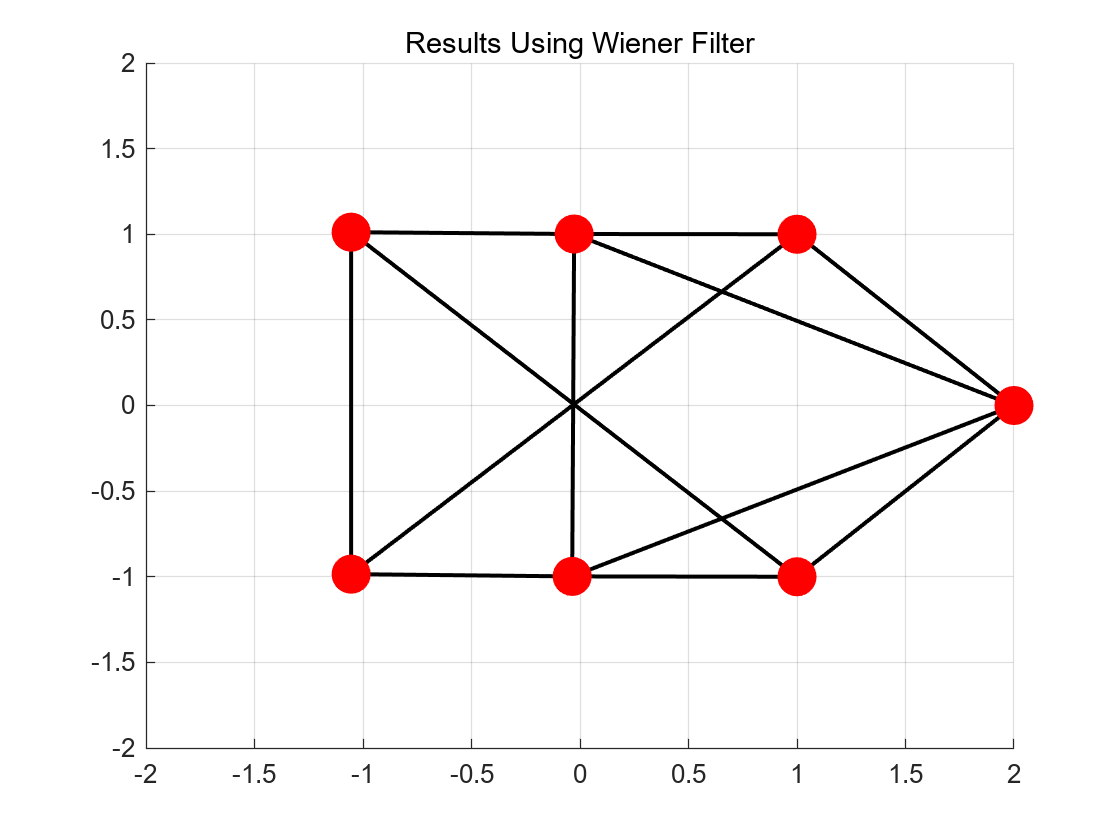

% Visualize final results
figure;
plot_formation(z_matrix_2(:, :, max_iter)); % Custom plotting function
grid on;
title("Results Using Wiener Filter"); % Title for the plot
saveas(gcf, fullfile('imgs', 'formation_wiener.png')); % Save the plot as an image

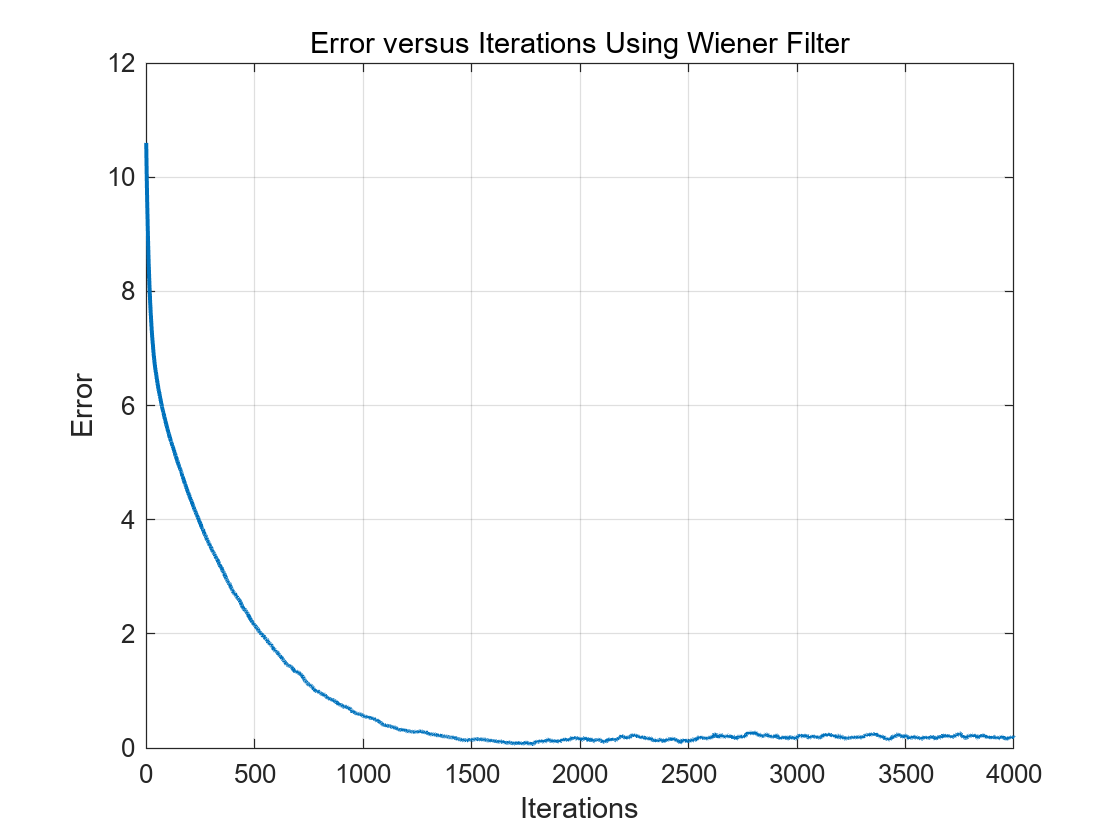


error_Wiener = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Wiener, 'LineWidth', 1.5);
xlabel("Iterations");
ylabel("Error");
grid on;
title("Error versus Iterations Using Wiener Filter");
saveas(gcf, fullfile('imgs', 'error_wiener.png'));

## 6. Comparison of Different Estimators

Here we plot the error curves of all the estimators to compare their performance. 

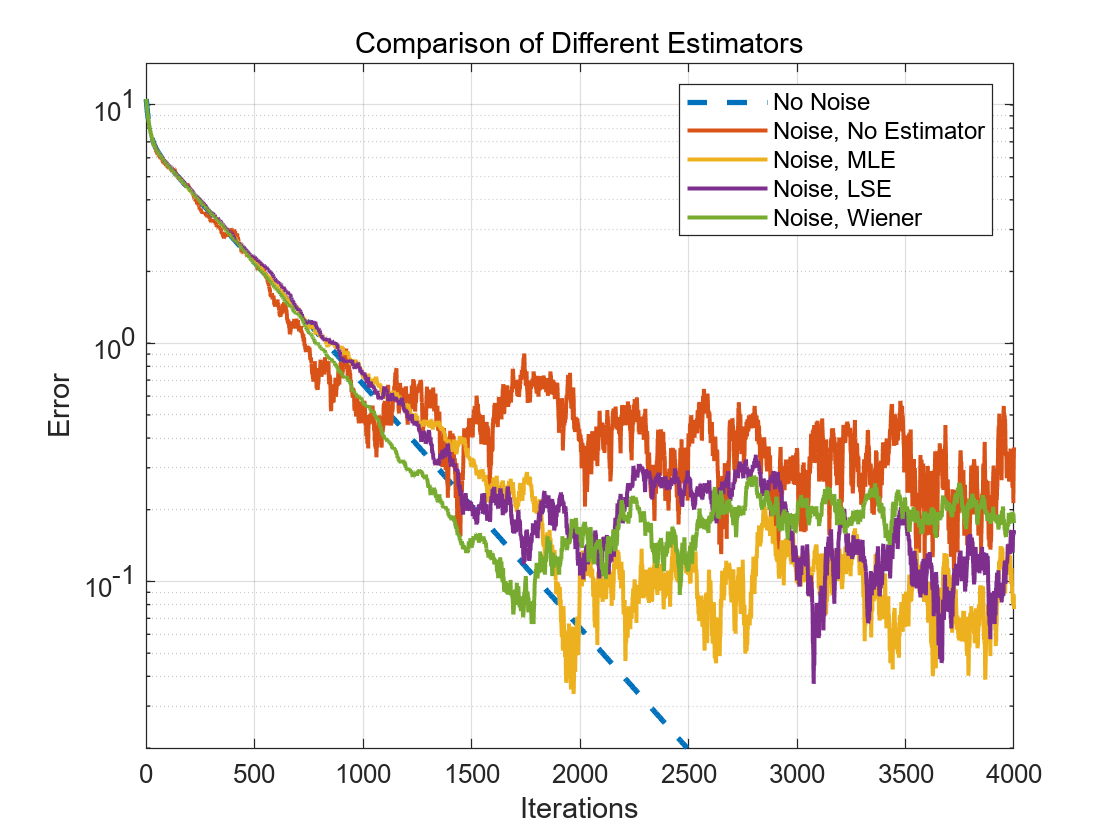

figure;
plot(error_no_noise, '--', 'LineWidth', 2);
hold on;
plot(error, 'LineWidth', 1.5);
hold on;
plot(error_MLE, 'LineWidth', 1.5);
hold on;
plot(error_LSE, 'LineWidth', 1.5);
hold on;
plot(error_Wiener, 'LineWidth', 1.5);
hold on;

grid on;
xlabel("Iterations");
ylabel("Error");
set(gca, 'YScale', 'log');
ylim([2e-2, 1.5e1]);
title("Comparison of Different Estimators");
legend('No Noise', 'Noise, No Estimator', 'Noise, MLE', 'Noise, LSE', 'Noise, Wiener');
saveas(gcf, fullfile('imgs', 'error_mle_lse_wiener.png'));

## 7. Comparison of Estimators with Different T

In this seciton, we explore how different T will influence the results. 

T_values = [5, 10, 20, 50]; % T values for Testing

### 7.1 MLE

Here we explore how different T influence the performance of MLE

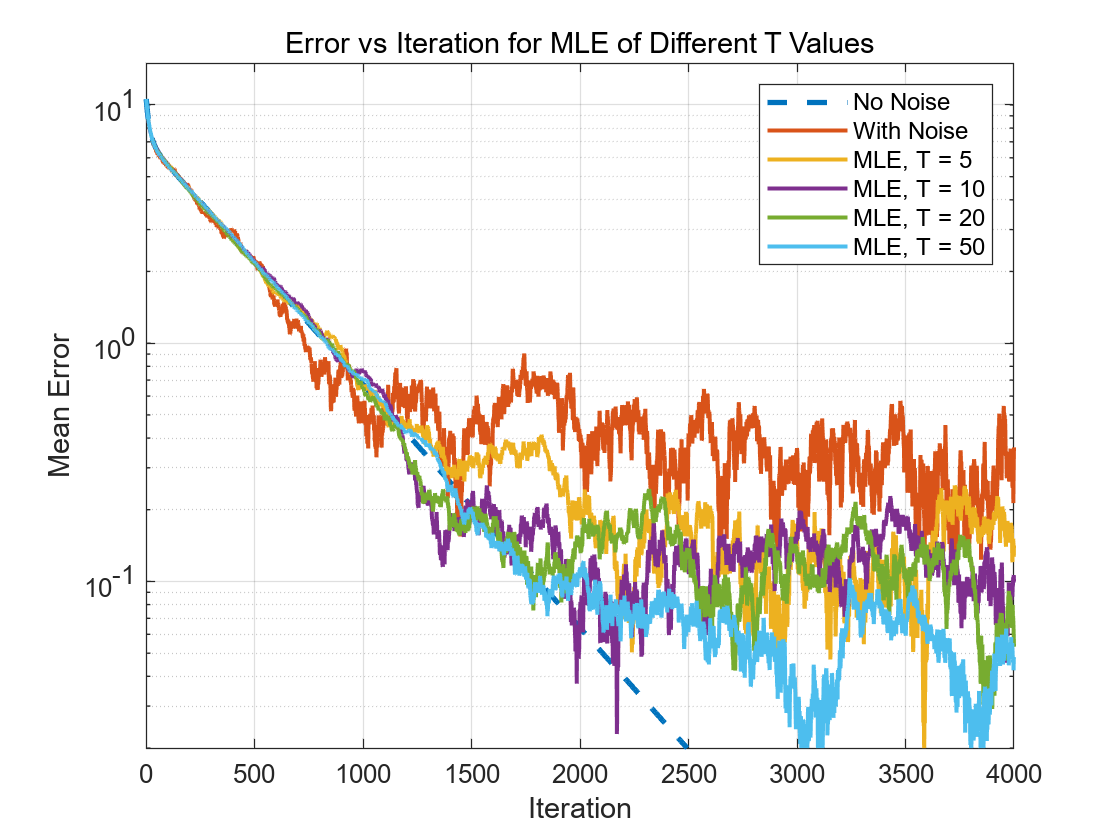

%% MLE
% Initialize errors for different T values
errors_different_T_lse = zeros(max_iter, length(T_values)); % Errors for varying T

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % Current T value
    vec_T = ones(T, 1);  % T x 1 vector of ones
    z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix
    z_matrix_2(:, :, 1) = z; % Initial state

    % Iterative process for the current T
    for k = 1:max_iter
        for i = 1:N
            % Step 1: Initialize input for node i
            u_i_k = zeros(1, dimension);

            % Step 2: Process neighboring nodes
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    % Generate noisy observations
                    vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T))); % Noise vector
                    H = kron(vec_T, I_Dimension);                           % Observation matrix
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);    % True relative state
                    x_state_m = H * dz_true' + vij_m';                      % Noisy observations

                    % Step 3: Compute MLE solution
                    Sigma_v = kron(R, eye(T));                              % Covariance matrix
                    Sigma_v_inv = inv(Sigma_v);                            % Inverse of covariance matrix
                    dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE solution

                    % Step 4: Accumulate input
                    u_i_k = u_i_k + L(i, j) * dz_mle';
                end
            end

            % Step 5: Update state for non-fixed nodes
            if i == 1 || i == 2 || i == 3 % Fixed nodes remain unchanged
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k; % Update state
            z_matrix_2(i, :, k + 1) = z_i_k_new;          % Save updated state
        end
    end

    % Compute error for the current T value
    errors_different_T_lse(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% Plot errors over iterations
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise'); % Baseline error without noise
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');             % Error with noise
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_lse(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['MLE, T = ' num2str(T_values(t_idx))]);
    hold on;
end

% Add legend and labels
legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
ylim([2e-2, 1.5e1]);       % Set y-axis limits
title('Error vs Iteration for MLE of Different T Values');
grid on;

% Save the plot
saveas(gcf, fullfile('imgs', 'error_different_T_mle.png')); % Save the plot as an image

### 7.2 LSE

Here we explore how different T influence the performance of LSE

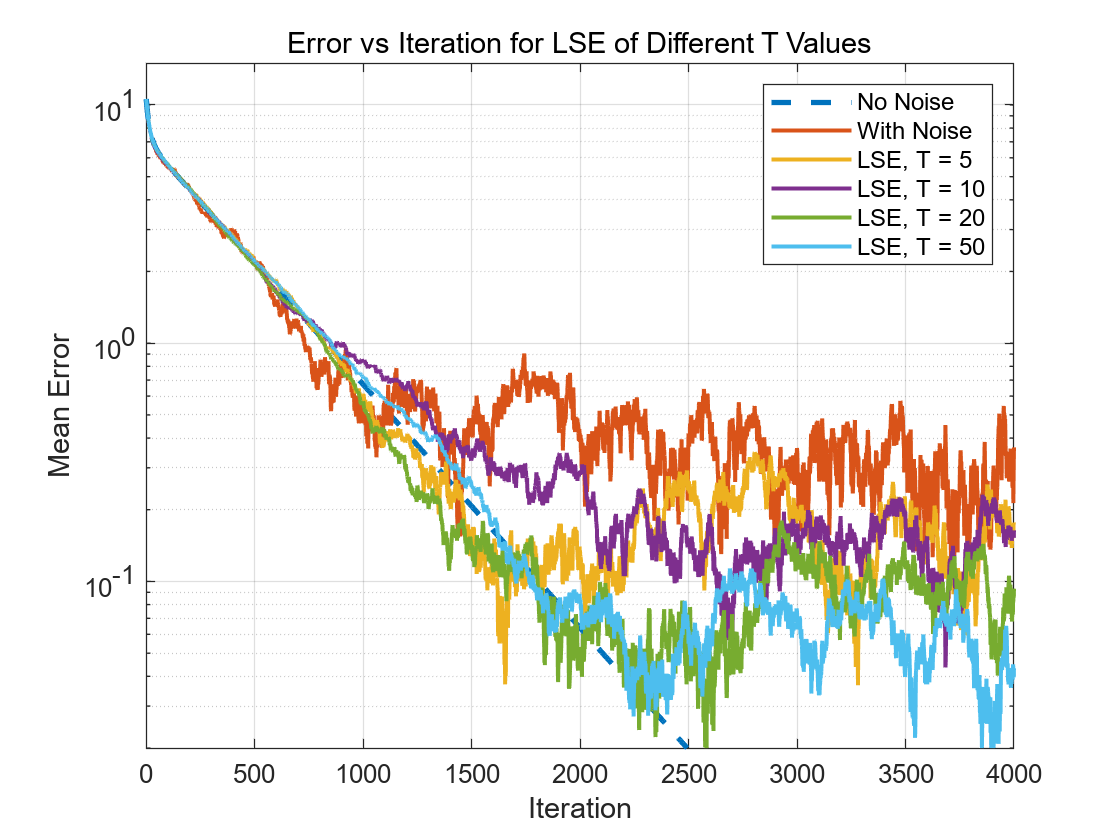

%% LSE
% Initialize error storage for different T values
errors_different_T_lse = zeros(max_iter, length(T_values)); % To store errors for different T

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % Current T value
    vec_T = ones(T, 1);  % T x 1 vector of ones
    z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix
    z_matrix_2(:, :, 1) = z; % Initial state

    % Start iterations
    for k = 1:max_iter
        for i = 1:N
            % Step 1: Initialize input for node i
            u_i_k = zeros(1, dimension);

            % Step 2: Process neighboring nodes
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    % Construct measurements
                    vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T))); % Noise vector
                    H = kron(vec_T, I_Dimension);                           % Observation matrix
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);    % Relative state
                    x_state_m = H * dz_true' + vij_m';                      % Noisy observations
                
                    % Step 3: Compute LSE solution
                    dz_lse = inv(H' * H) * (H' * x_state_m);                % LSE solution

                    % Step 4: Accumulate input
                    u_i_k = u_i_k + L(i, j) * dz_lse';
                end
            end

            % Step 5: Update state for non-fixed nodes
            if i == 1 || i == 2 || i == 3 % Fixed nodes remain unchanged
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k; % Update state
            z_matrix_2(i, :, k + 1) = z_i_k_new;          % Save updated state
        end
    end

    % Compute error for the current T value
    errors_different_T_lse(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% Plot errors over iterations
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise'); % Baseline error without noise
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');             % Error with noise
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_lse(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['LSE, T = ' num2str(T_values(t_idx))]);
    hold on;
end

% Add legend and labels
legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
ylim([2e-2, 1.5e1]);       % Set y-axis limits
title('Error vs Iteration for LSE of Different T Values'); % Title of the plot
grid on;

% Save the plot as an image
saveas(gcf, fullfile('imgs', 'error_different_T_lse.png'));

### 7.3 Wiener

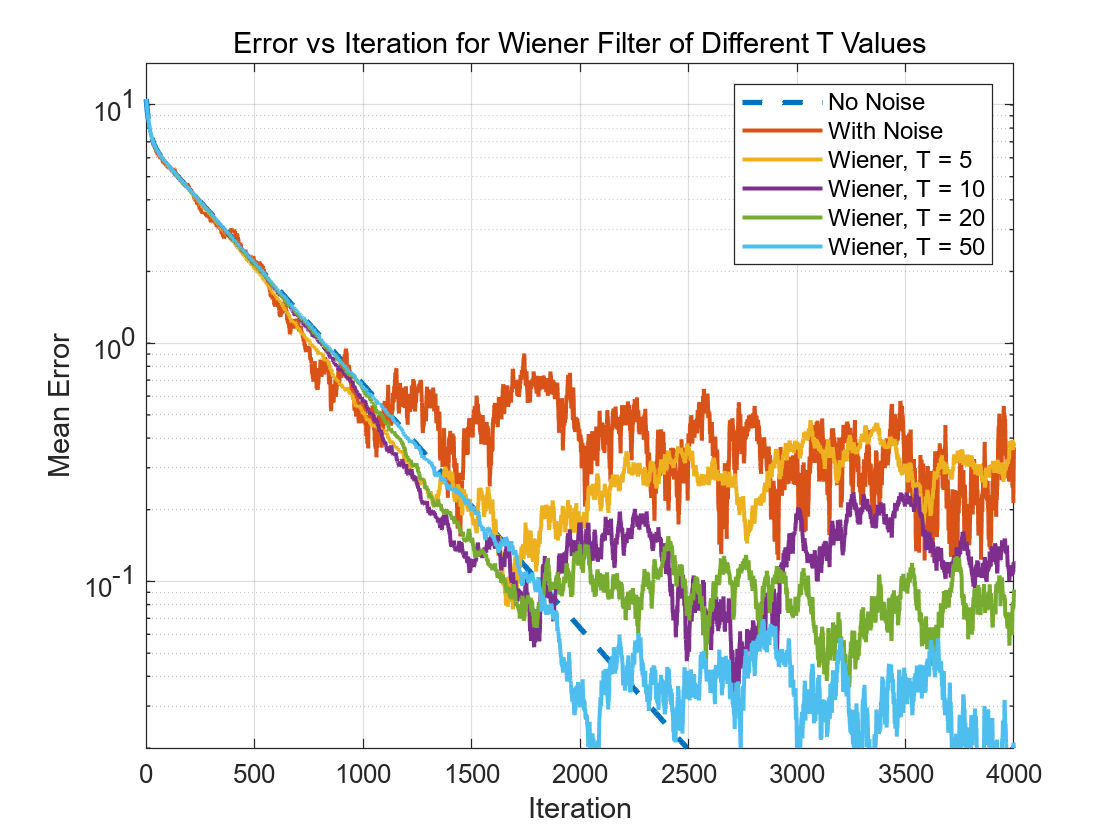

%% Wiener
% Initialize error storage for different T values
errors_different_T_Wiener = zeros(max_iter, length(T_values)); % To store errors for different T

for t_idx = 1:length(T_values)
    T = T_values(t_idx); % Current T value
    R_extended = kron(eye(T), R);           % Noise covariance matrix
    vec_T = ones(T, 1);                     % T x 1 vector of ones
    z_matrix_2 = zeros(7, 2, max_iter + 1); % State matrix
    z_matrix_2(:, :, 1) = z;                % Initial state

    % Start iterations
    for k = 1:max_iter
        for i = 1:N
            % Step 1: Initialize input for node i
            u_i_k = zeros(1, dimension);

            % Step 2: Process neighboring nodes
            for j = 1:N
                if L(i, j) ~= 0 && i ~= j
                    % Compute relative state
                    dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % True relative state (1x2)
                    
                    % Generate noisy observations
                    vij_m = mvnrnd(zeros(1, T * dimension), R_extended); % Noise vector
                    H = kron(vec_T, I_Dimension);                       % Measurement matrix (T*2 x 2)
                    x_state_m = H * dz_true' + vij_m';                  % Noisy observations (T*2 x 1)
                
                    % Step 3: Compute Wiener filter covariance matrices
                    R_ss = dz_true' * dz_true;                          % Autocorrelation of the true signal (2x2)
                    R_xx = H * R_ss * H' + R_extended;                  % Covariance of the observed signal (T*2 x T*2)
                    C_theta_x = R_ss * H';                              % Cross-covariance between signal and observation (2xT*2)
                
                    % Step 4: Compute Wiener filter weight matrix
                    W = C_theta_x / R_xx;                               % Wiener filter weights (2xT*2)
                
                    % Step 5: Estimate relative state using Wiener filter
                    dz_estimate = W * x_state_m;                        % Wiener filter estimation (2x1)
                
                    % Step 6: Accumulate input
                    u_i_k = u_i_k + L(i, j) * dz_estimate';
                end
            end

            % Step 7: Update state for non-fixed nodes
            if i == 1 || i == 2 || i == 3 % Fixed nodes remain unchanged
                u_i_k = 0;
            end
            z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k; % Update state
            z_matrix_2(i, :, k + 1) = z_i_k_new;          % Save updated state
        end
    end

    % Compute error for the current T value
    errors_different_T_Wiener(:, t_idx) = compute_error(z_matrix_2, z_star, max_iter);
end

% Plot errors over iterations
figure;
plot(error_no_noise, '--', 'LineWidth', 2, 'DisplayName', 'No Noise'); % Baseline error without noise
hold on;
plot(error, 'LineWidth', 1.5, 'DisplayName', 'With Noise');             % Error with noise
hold on; 
for t_idx = 1:length(T_values)
    plot(errors_different_T_Wiener(:, t_idx), 'LineWidth', 1.5, 'DisplayName', ['Wiener, T = ' num2str(T_values(t_idx))]);
    hold on;
end

% Add legend and labels
legend('show');
xlabel('Iteration');
ylabel('Mean Error');
set(gca, 'YScale', 'log'); % Set y-axis to logarithmic scale
ylim([2e-2, 1.5e1]);       % Set y-axis limits
title('Error vs Iteration for Wiener Filter of Different T Values'); % Title of the plot
grid on;

% Save the plot as an image
saveas(gcf, fullfile('imgs', 'error_different_T_wiener.png')); % Save the plot as an image